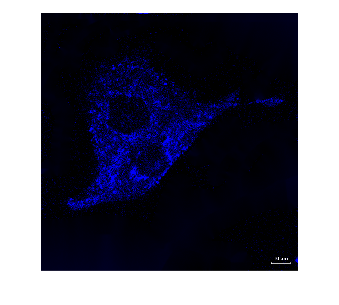

GrayImg_adjusted_405 = 1024×1024 uint8 矩阵
    82    51     0    20   112   112    51    51    51     0     0     0     0    51     0     0    82    20    20     0     0    20    20     0     0    20     0     0    20    82    20     0    20     0    82   112    51    51     0     0     0    82    82     0     0     0   143    51     0    20
     0    10    10    20    10    10    10    10    20    10    20    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10
     0    10    10    10    10    10    10    10    10    10    10    10    10    10    10    20    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10
     0    10    20    10    20    10    20    10    20 

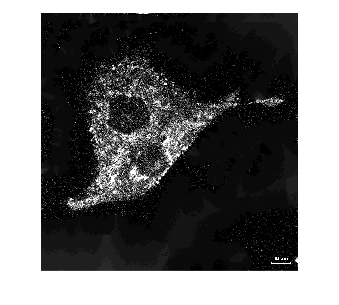

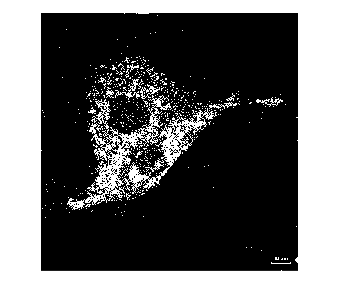

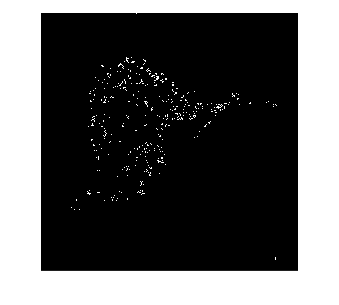

%读取488通道荧光图像

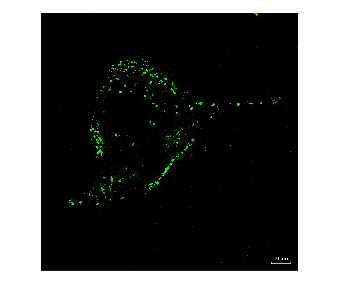

orImg_488=imread("C:\Users\zxsh1\Desktop\Pro3-Image Analysis\488.png");
figure
imshow(orImg_488);

%将488通道荧光图像转换为灰度图
GrayImg_488=rgb2gray(orImg_488);
GrayImg_adjusted_488=imadjust(GrayImg_488)

GrayImg_adjusted_488 = 1024×1024 uint8 矩阵
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0 

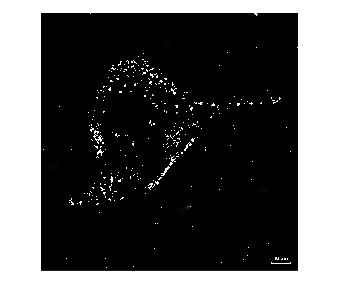

figure
imshow(GrayImg_adjusted_488);

%488灰度图转换为二值图
GrayImg_norm_488=mat2gray(GrayImg_adjusted_488)

GrayImg_norm_488 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0

level=0.6

level = 0.6000

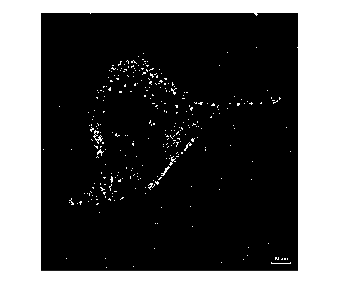

BinaryImg_488=imbinarize(GrayImg_norm_488,level);
figure
imshow(BinaryImg_488);

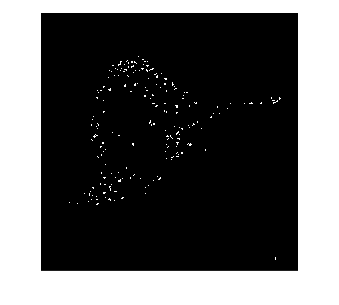

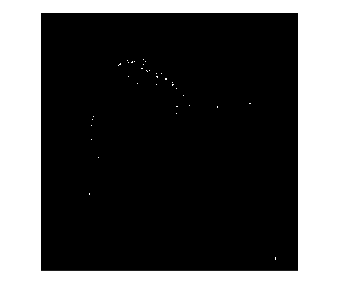

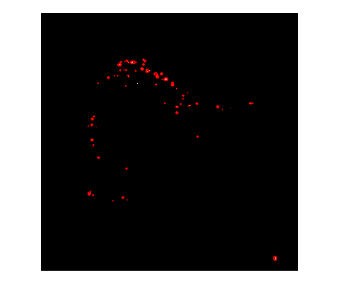

%488二值图过滤
BinaryImg2_488=bwpropfilt(BinaryImg_488,"Area",[5 100]);
figure
imshow(BinaryImg2_488);

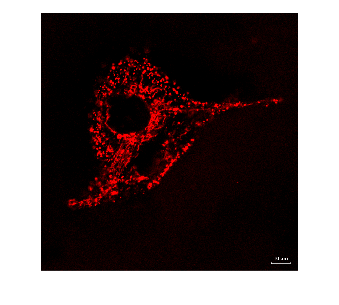

%读取647通道荧光图像
orImg_647=imread("C:\Users\zxsh1\Desktop\Pro3-Image Analysis\647.png");
figure
imshow(orImg_647);

%将647荧光图像转换为灰度图
GrayImg_647=rgb2gray(orImg_647);
GrayImg_adjusted_647=imadjust(GrayImg_647)

GrayImg_adjusted_647 = 1024×1024 uint8 矩阵
    0   10    0    3   10    0    7    7   13    3   13   17   10   13   17   13   13    0    3    3    3   17   13   10    0    0   10    0    3    3    7    0   13    0    3   10    7   13    3   10    3    0   10   13   10   17   17    3    3    0
    3   13   13    3    0   23    7    7   17    3    0   13   13    7    7    3   23    0   13    7    7    3    7    7   10   13    0   13   13   10   17   10    3    0   13    3    3   17    0   13   13    7   10   10    7    3   13   10    0   13
    3   20    0    7    7   10    3   10    0   20    0    3   10   13    7   10    0    3    0    0    0    7   13   13   13   10   23    3    7   13    3    3    3   13   17    3   23   13    7   13    7   17    0    3    0    3   10    0    0    3
    3    7    3   13   13    0    7    3   10    7   10   27    0    0    3   20    0    0   17    0    0   13    3    0    3   13   10    3   10   20    0    0    0    3   23    7    3   13   10    7   10

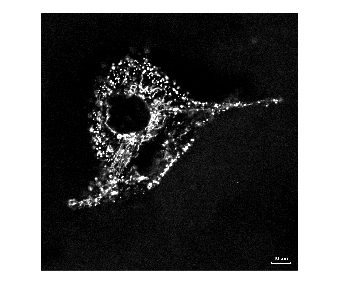

figure
imshow(GrayImg_adjusted_647);

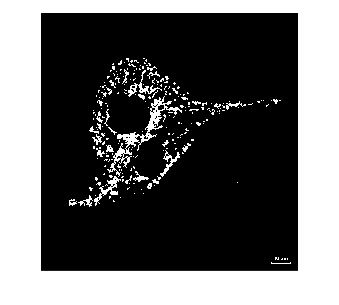

%647灰度图转换为二值图
BinaryImg_647=imbinarize(GrayImg_adjusted_647);
figure
imshow(BinaryImg_647);

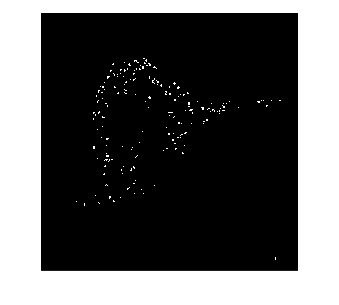

%647二值图过滤
BinaryImg2_647=bwpropfilt(BinaryImg_647,"Area",[5 100]);
figure
imshow(BinaryImg2_647);

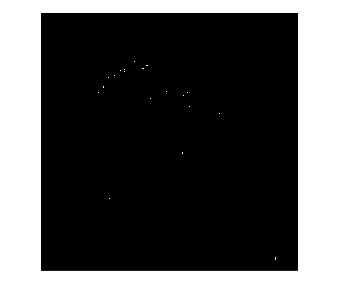

%计算488+647共定位区域
BinaryImg_SUM_2=and(BinaryImg2_488,BinaryImg2_647);
figure
imshow(BinaryImg_SUM_2);

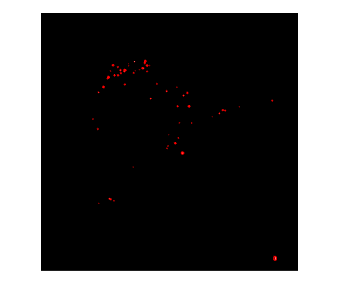

%标注488+647共定位区域
L=bwlabel(BinaryImg_SUM_2);
img_reg=regionprops(BinaryImg_SUM_2,"Area","BoundingBox");
areas=[img_reg.Area];
rects=cat(1, img_reg.BoundingBox);
imshow(BinaryImg_SUM_2);
for i=1:size(rects, 1)
    rectangle('Position',rects(i,:),'EdgeColor','r');
    
end